clc; close all; clear all; warning off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% d_prime_s_res=0.2;  %% maximum distance resolution, m
% 
% tau_s_0=[0.0001,0.001,0.002,0.003,0.004,0.005,0.008,0.01,0.015,0.02]; %%  threshold in sensing

tau_c_0=[0.05,0.1,0.15,0.2,0.25,0.3,0.35,0.4,0.45,0.5];  %% threshold/required data rate in communication

gamma_bs= 50/1000^2;  %%  density of base station, point/m^2

gamma_sct= 300/1000^2; %% density of SCT, point/m^2

gamma_st= 300/1000^2;   %% density of ST, point/m^2

eta=0.5;  %% first \beta part of the spectrum is allocated to sensing

mu=0.5;  %%  first \mu part of the power is allocated to sensing

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
run('parameters.mlx');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Ana_P_c_cov=zeros(length(tau_c_0),1);
Sim_P_c_cov=zeros(length(tau_c_0),1);

for tt=1:length(tau_c_0)
    
    tau_c=tau_c_0(1,tt)
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    int_c1=@(r_bt) exp(-tau_c    *N_0*B_c*1e6      *f_c^2*r_bt^1.9/P_ct/g_cb*10^(0.1*(L_gr+L_ai)-2.8)); %% B_c is with the unit of MHz
    
    int_c2=@(r_bt) integral( @(r_bjt)  tau_c/(tau_c+(r_bjt/r_bt)^1.9)*r_bjt, r_bt, r_bjt_max,"ArrayValued",true);
    
    A_cj=@(r_bjtj) atan(C_d/2/r_bjtj)/pi;
    
    f_r_bjtj=@(r_bjtj) 2*pi*gamma_sct*r_bjtj*exp(-pi*gamma_sct*r_bjtj^2);
    
    int_c3=@(r_bt)  integral( @(r_bjtj)  exp(-2*pi*gamma_bs*A_cj(r_bjtj)* int_c2(r_bt))* f_r_bjtj(r_bjtj) , 0, r_bjtj_max, "ArrayValued",true );
    
    Ana_P_c_cov(tt,1)=  integral(@(r_bt)  int_c1(r_bt)* int_c3(r_bt)*  2*pi*gamma_bs*r_bt*exp(-pi*gamma_bs*r_bt^2), 0, r_bt_max, "ArrayValued",true );
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    iteration=100000;
    
    SINR_c=zeros(1,iteration);
    parfor ii=1:iteration
        
        [BS_xy_R_sort,R_bt,R_bjt,SCT_j_xy,theta_j] = make_BS_SCT(range_xy_BS,range_xy_SCT,gamma_bs,gamma_sct,C_d,r_bt_max,r_bjt_max,r_bjtj_max);
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
        P_cr_Rbt=P_ct*10^2.8/f_c^2/R_bt^1.9/10^(0.1*(L_gr+L_ai))*exprnd(1)*g_cb;
        
        I_c= P_ct*10^2.8/f_c^2./R_bjt.^1.9/10^(0.1*(L_gr+L_ai))*exprnd(1)*g_cb .*theta_j'/2/pi ;
        I_c=sum(I_c);
        
        SINR_c(1,ii)=P_cr_Rbt/(N_0*B_c*1e6+I_c);  %% B_c is with the unit of MHz
        
    end
    Sim_P_c_cov(tt,1)=sum(SINR_c >= tau_c)/iteration;
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
end

tau_c = 0.0500

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 20).


tau_c = 0.1000

tau_c = 0.1500

tau_c = 0.2000

tau_c = 0.2500

tau_c = 0.3000

tau_c = 0.3500

tau_c = 0.4000

tau_c = 0.4500

tau_c = 0.5000

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
save('data/Ana_P_c_cov.mat','Ana_P_c_cov');
save('data/Sim_P_c_cov.mat','Sim_P_c_cov');



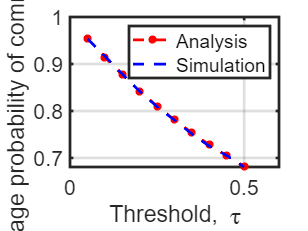


figure();

plot(tau_c_0, Ana_P_c_cov,'--*r','LineWidth',2);hold on;
plot(tau_c_0, Sim_P_c_cov,'--b','LineWidth',2);hold on;

legend('Analysis','Simulation');
xlabel('Threshold, \tau');
ylabel('Coverage probability of communictaion' );



set(gca,'LineWidth',2,'FontSize',16);
grid on;